% using MDL and AIC to find source number, and MUSIC to find DOAs
clear(); close all;

wavelength = 1; % normalized
d = wavelength / 2;
design_ula = design_array_1d('ula', 6, d);
% doas = linspace(-pi/8, pi/3, 8);
doas = [0, 0.5];
power_source = 1;
% power_noise = 1;
SNR_dB = 0;
power_noise = power_source / (10^(SNR_dB/10));
snapshot_count = 1000;
source_count = length(doas);

% stochastic (unconditional) model
[~, R] = snapshot_gen_sto(design_ula, doas, wavelength, snapshot_count, power_noise, power_source);

% source number detection
[~, l] = eig(0.5*(R+R'), 'vector');
l = flipud(l);
n_mdl = sn_mdl(l, design_ula.element_count, snapshot_count);
n_aic = sn_aic(l, design_ula.element_count, snapshot_count);
fprintf('There are %d sources.\n', source_count);

There are 2 sources.


fprintf('# of sources estimated by MDL = %d\n', n_mdl);

# of sources estimated by MDL = 2


fprintf('# of sources estimated by AIC = %d\n', n_aic);

# of sources estimated by AIC = 2



% normal MUSIC
tic;
sp_normal = music_1d(R, source_count, design_ula, wavelength, 180, 'RefineEstimates', true);
toc;

历时 0.001218 秒。


sp_normal.true_positions = doas;
fprintf('[MUSIC] Estimated DOAs:\n');

[MUSIC] Estimated DOAs:


disp(sp_normal.x_est);

   -0.0009    0.5039



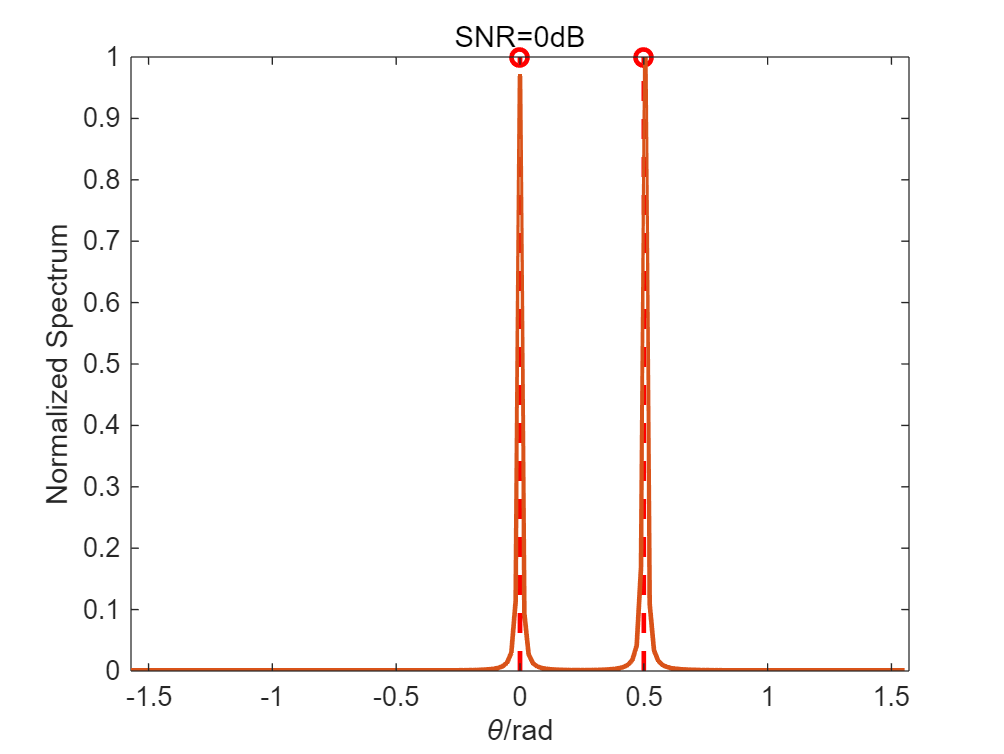

plot_sp(sp_normal, 'title', 'SNR=0dB', 'PlotType', 'cartesian', 'LineWidth', 1.75);